addpath('./functions');
addpath('./data');

dataset = [];
classes = [];
for i=1:5
    str = ['data\cifar-10-batches-mat\data_batch_', num2str(i),'.mat'];
    load(str)
    dataset = [dataset; data];
    classes = [classes; labels];

end

load('data\cifar-10-batches-mat\test_batch.mat');

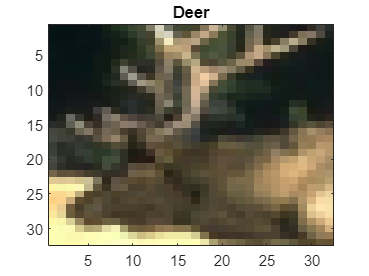

[permutedImageData, categoricalLabels] = permute_dataset(dataset, classes);
labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(permutedImageData,4));

imagesc(permutedImageData(:,:,:,idx))
title(label2name(categoricalLabels(idx)))

layers = basic_cnn_classifier()

layers =   13×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     5   ''   ReLU                    ReLU
     6   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     7   ''   ReLU                    ReLU
     8   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     9   ''   Fully Connected         128 fully connected layer
    10   ''   ReLU                    ReLU
    11   ''   Fully Connected         10 fully connected layer
    12   ''   Softmax                 softmax
    13   ''   Classification Output   crossentropyex

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |        6.25% |       2.3084 |          0.0100 |
|       1 |          50 |       00:00:05 |       42.19% |       1.7833 |          0.0100 |
|       1 |         100 |       00:00:08 |       34.38% |       1.6877 |          0.0100 |
|       1 |         150 |       00:00:11 |       45.31% |       1.5088 |          0.0100 |
|       1 |         200 |       00:00:15 |       42.19% |       1.5264 |          0.0100 |
|       1 |         250 |       00:00:30 |       48.44% |       1.5394 |          0.0100 |
|       1 |         300 |       00:00:51 |       55

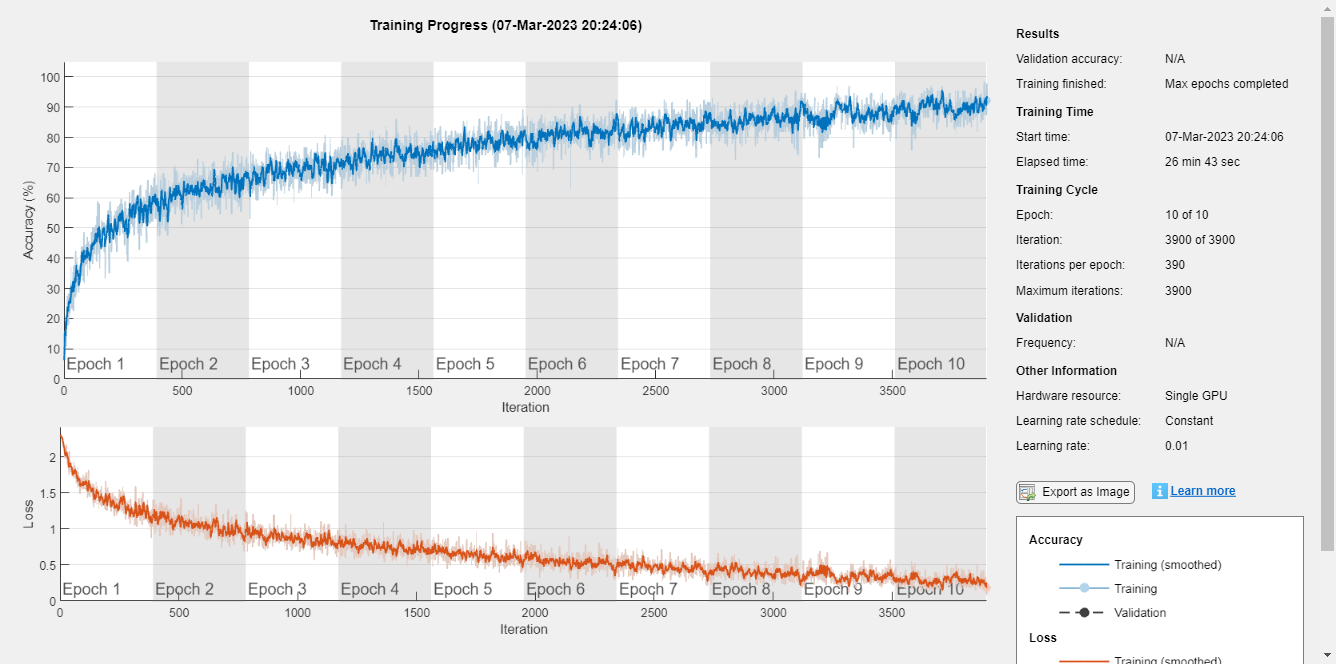

options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",Plots="training-progress", MaxEpochs=10);
net = trainNetwork(permutedImageData,categoricalLabels, layers, options);

[testData, testLabels] = permute_dataset(data,labels);

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 66.02%


test_size = 0.2

test_size = 0.2000

% normalizedData = normalize_data(permutedImageData);
[X_train, X_test, Y_train, Y_test] = train_test_split(permutedImageData, categoricalLabels, test_size);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |        7.03% |        9.50% |       2.3050 |       2.3022 |          0.0100 |
|       1 |          50 |       00:02:03 |       23.44% |       20.20% |       2.0114 |       2.0972 |          0.0100 |
|       2 |         100 |       00:04:03 |       37.50% |       37.30% |       1.6623 |       1.7162 |          0.0100 |
|       3 |         150 |       00:05:55 |       40.62% |       41.60% |       1.6715 |       1.6124 |          0.

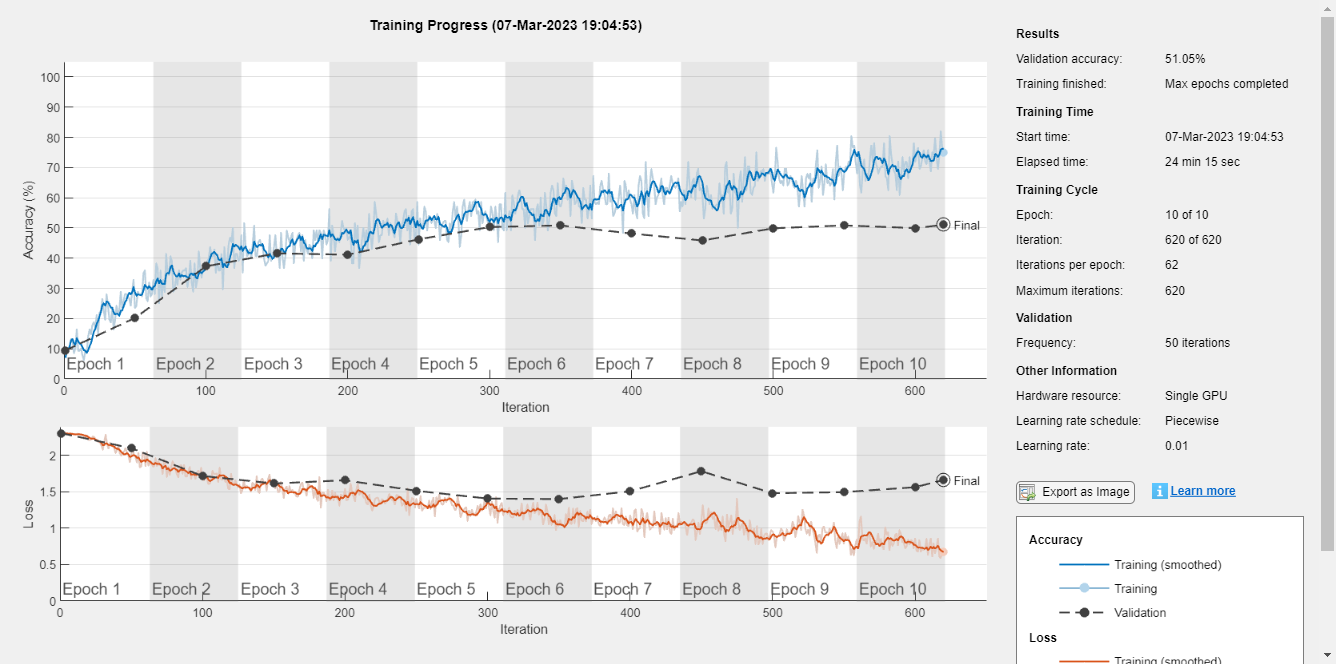

layers = basic_cnn_classifier();
options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",ValidationData={X_test, Y_test},Plots="training-progress", MaxEpochs=10, LearnRateSchedule="piecewise");
net = trainNetwork(X_train ,Y_train, layers, options);